# Varying Parameters analysis

**Author(s): Vanja Vlasov, Systems Biochemistry Group, LCSB, University of Luxembourg.**

**Reviewer(s): Thomas Pfau, Systems Biology Group, LSRU, University of Luxembourg.**

**Ines Thiele, Systems Biochemistry Group, LCSB, University of Luxembourg**

In this tutorial, we show how computations are performed by varying one or two parameters over a fixed range of numerical values.

## EQUIPMENT SETUP

If necessary, initialise the cobra toolbox:

initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

For solving linear programming problems in the analysis, certain solvers are required:

changeCobraSolver ('gurobi', 'all', 1);


 > Gurobi interface added to MATLAB path.
 > Solver for LPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQPproblems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


The present tutorial can run with `'glpk``'` package, which does not require additional installation and configuration. Although, for the analysis of large models is recommended to use the `'gurobi'` package. For detail information, refer to the solver installation guide: [https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md)

## PROCEDURE

Before proceeding with the simulations, the path for the model needs to be set up:

pathModel = '~/work/sbgCloud/data/models/unpublished/Recon3D_models/';
filename = '2017_04_28_Recon3d.mat';
load([pathModel, filename])
model = modelRecon3model;
clear modelRecon3model

In this tutorial, the provided model is a generic model of the human cellular metabolism, Recon 3D [1]. Therefore, we assume, that the cellular objectives include energy production or optimisation of uptake rates and by-product secretion for various physiological functions of the human body.

## TROUBLESHOOTING

If there are multiple energy sources available in the model; Specifying more constraints is necessary. If we do not do that, we will have additional carbon and oxygen energy sources available in the cell and the maximal ATP production. 

To avoid this issue, all external carbon sources need to be closed.

%Closing the uptake of all energy and oxygen sources
idx=strmatch('Exchange/demand reaction', model.subSystems);
c=0;
for i=1:length(idx)
    if model.lb(idx(i))~=0
        c=c+1;
        uptakes{c}=model.rxns{idx(i)};
    end
end

modelalter = model;
modelalter = changeRxnBounds(modelalter, uptakes, 0, 'b');

% The alternative way to do that, in case you were using another large model, 
% that does not contain defined Subsystem is
% to find uptake exchange reactions with following codes:
% [selExc, selUpt] = findExcRxns(model);
% uptakes = model.rxns(selUpt);
% Selecting from the exchange uptake reactions those 
% which contain at least 1 carbon in the metabolites included in the reaction:
% subuptakeModel = extractSubNetwork(model, uptakes);
% hiCarbonRxns = findCarbonRxns(subuptakeModel,1);
% Closing the uptake of all the carbon sources
% modelalter = model;
% modelalter = changeRxnBounds(modelalter, hiCarbonRxns, 0, 'l');

## Robustness analysis

Robustness analysis is applied to estimate and visualise how changes in the concentration of an environmental parameter (exchange rate) or internal reaction effect on the objective [2]. If we are interested in varying $$v_{j}$ between two values, i.e., $$v_{j,min}$ and $$v_{j,max}$, we can solve $$l$ optimisation problems:


$$\begin{array}{ll}
\max Z_{k}= c^{T}v \\
\text{s.t.} & k =1,...,l,\\
& Sv=0,\\
\text{fixing} & v_{j}=v_{j,min}+ \frac{(k-1)}{(l-1)}*(v_{j,max}-v_{j,min})\\
\text{constraints} & v_{i,min}\leq v_{i} \leq v_{i,max}, i=1,...,n,i \neq j
 \end{array}$$


The function `robustnessAnalysis()` is used for this analysis:

% [controlFlux, objFlux] = robustnessAnalysis(model, controlRxn, nPoints,...
%      plotResFlag, objRxn,objType)

where inputs are a COBRA model, a reaction that has been analysed and optional inputs:

% INPUTS
% model         COBRA model structure
% controlRxn    Reaction of interest whose value is to be controlled
%
% OPTIONAL INPUTS
% nPoints       Number of points to show on plot (Default = 20)
% plotResFlag   Plot results (Default true)
% objRxn        Objective reaction to be maximized
%               (Default = whatever is defined in model)
% objType       Maximize ('max') or minimize ('min') objective
%               (Default = 'max')
%
% OUTPUTS
% controlFlux   Flux values within the range of the maximum and minimum for
%               a reaction of interest
% objFlux       Optimal values of objective reaction at each control
%               reaction flux value

Here, we will investigate how robust the maximal ATP production of the network (i.e., the maximal flux through '`DM_atp_c_'`) is with respect to varying glucose uptake rates and fixed oxygen uptake. 

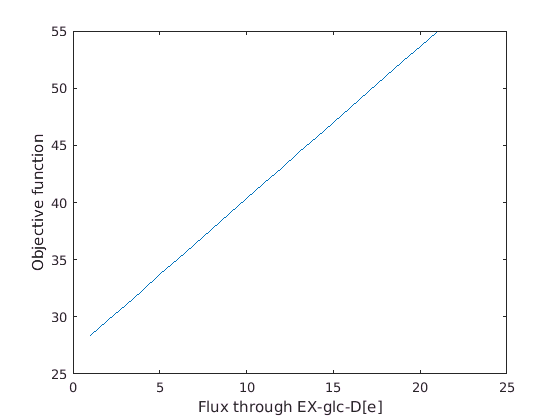

modelrobust = modelalter;
modelrobust = changeRxnBounds(modelrobust, 'EX_o2[e]', -17, 'b');
AtpRates = zeros(21, 1);
for i = 0:20
    modelrobust = changeRxnBounds(modelrobust, 'EX_glc_D[e]', -i, 'b');
    modelrobust = changeObjective(modelrobust, 'DM_atp_c_');
    FBArobust = optimizeCbModel(modelrobust, 'max');
    AtpRates(i+1) = FBArobust.f;
end
plot (1:21, AtpRates)
xlabel('Flux through EX-glc-D[e]')
ylabel('Objective function')

We can also investigate the robustness of the maximal ATP production when the available glucose amount is fixed, while different levels of oxygen are available.

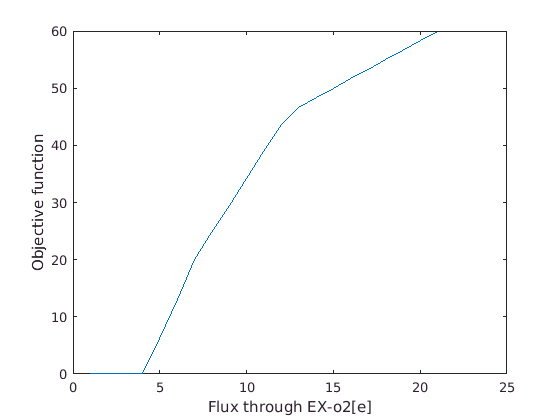

modelrobustoxy = modelalter;
modelrobustoxy = changeRxnBounds(modelrobustoxy, 'EX_glc_D[e]', -20, 'b');
AtpRatesoxy = zeros(21, 1);
for i = 0:20
    modelrobustoxy = changeRxnBounds(modelrobustoxy, 'EX_o2[e]', -i, 'b');
    modelrobustoxy = changeObjective(modelrobustoxy, 'DM_atp_c_');
    FBArobustoxy = optimizeCbModel(modelrobustoxy, 'max');
    AtpRatesoxy(i+1) = FBArobustoxy.f;
end
plot (1:21, AtpRatesoxy)
xlabel('Flux through EX-o2[e]')
ylabel('Objective function')

-        **Double robust analysis**

Performs robustness analysis for a pair of reactions of interest and an objective of interest. The double robust analysis is implemented with the function `doubleRobustnessAnalysis()`.

% [controlFlux1, controlFlux2, objFlux] = doubleRobustnessAnalysis(model,...
%  controlRxn1, controlRxn2, nPoints, plotResFlag, objRxn, objType)

The inputs are a COBRA model, two reactions for the analysis and optional inputs:

%INPUTS
% model         COBRA model to analyse,
% controlRxn1   The first reaction for the analysis,
% controlRxn2   The second reaction for the analysis;
%
%OPTIONAL INPUTS
% nPoints       The number of flux values per dimension (Default = 20)
% plotResFlag   Indicates whether the result should be plotted (Default = true)
% objRxn        is objective to be used in the analysis (Default = whatever
%               is defined in model)
% objType       Direction of the objective (min or max)
%               (Default = 'max')

Double robustness analysis in progress ...
1%      [                                        ]2%      [                                        ]3%      [.                                       ]4%      [.                                       ]5%      [..                                      ]6%      [..                                      ]7%      [..                                      ]8%      [...                                     ]9%      [...                                     ]10%     [....                                    ]11%     [....                                    ]12%     [....                                    ]13%     [.....                                   ]14%     [.....                                   ]15%     [......                                  ]16%     [......                                  ]17%     [......                                  ]18%     [.......                                 ]19%     [.......                                 ]20%    

controlFlux1 =   -20.0000
  -17.7778
  -15.5556
  -13.3333
  -11.1111
   -8.8889
   -6.6667
   -4.4444
   -2.2222
         0


controlFlux2 =   -17.0000
  -15.1111
  -13.2222
  -11.3333
   -9.4444
   -7.5556
   -5.6667
   -3.7778
   -1.8889
         0


objFlux =    55.0000   51.8519   48.7037   45.2632   36.3158   27.3684   17.6923    4.6154         0         0
   52.0370   48.8889   45.7407   42.5926   37.2515   28.3041   19.3567    7.0085         0         0
   49.0741   45.9259   42.7778   39.6296   36.4815   29.2398   20.2924    9.4017         0         0
   46.1111   42.9630   39.8148   36.6667   33.5185   30.1754   21.2281   11.7949         0         0
   43.1481   40.0000   36.8519   33.7037   30.5556   27.4074   22.1637   13.2164         0         0
   40.1852   37.0370   33.8889   30.7407   27.5926   24.4444   21.2963   14.1520    3.5043         0
   37.2222   34.0741   30.9259   27.7778   24.6296   21.4815   18.3333   15.0877    5.8974         0
   34.2593   31.1111   27.9630   24.8148   21.6667   18.5185   15.3704   12.2222    7.0760         0
   31.2963   28.1481   25.0000   21.8519   18.7037   15.5556   12.4074    9.2593    6.1111         0
   28.3333   25.1852   22.0370   18.8889   15.7407   12.5926    9.4444    6.2963 

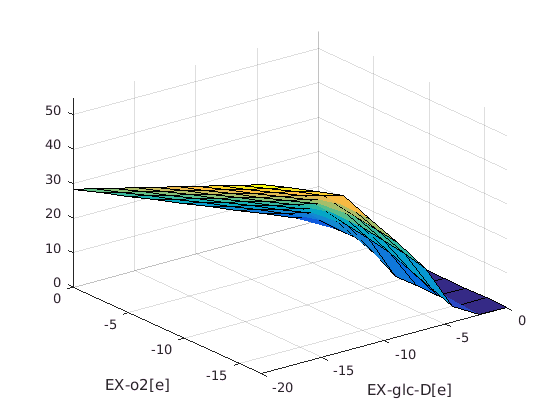

modeldrobustoxy = modelalter;
modeldrobustoxy = changeRxnBounds(modeldrobustoxy, 'EX_glc_D[e]', -20, 'l');
modeldrobustoxy = changeRxnBounds(modeldrobustoxy, 'EX_o2[e]', -17, 'l');
[controlFlux1, controlFlux2, objFlux] = doubleRobustnessAnalysis(modeldrobustoxy,...
    'EX_glc_D[e]', 'EX_o2[e]', 10, 1, 'DM_atp_c_', 'max')

## **Phenotypic phase plane analysis (PhPP)**

The PhPP is a method for describing in two or three dimensions, how the objective function would change if additional metabolites were given to the model [3]. 

Essentially PhPP performs a `doubleRobustnessAnalysis()`, with the difference that shadow prices are retained. The code is as follows-

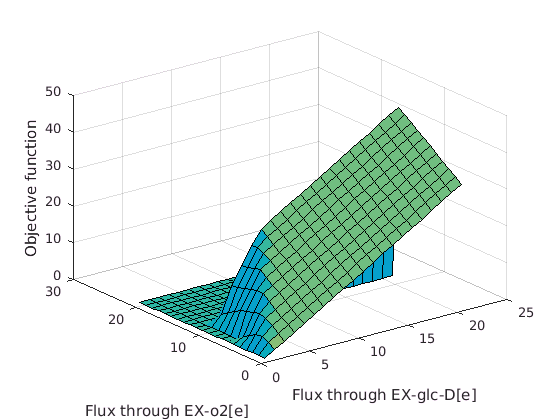

modelphpp = modelalter;
ATPphppRates = zeros(21);
for i = 0:10
    for j = 0:20
        modelphpp = changeRxnBounds(modelphpp, 'EX_glc_D[e]', -i, 'b');
        modelphpp = changeRxnBounds(modelphpp, 'EX_o2[e]', -j, 'b');
        modelphpp = changeObjective(modelphpp, 'DM_atp_c_');
        FBAphpp = optimizeCbModel(modelphpp, 'max');
        ATPphppRates(i+1,j+1) = FBAphpp.f;
    end
end

surfl(ATPphppRates) % 3d plot
xlabel('Flux through EX-glc-D[e]')
ylabel('Flux through EX-o2[e]')
zlabel('Objective function')

To generate a 2D plot: `pcolor(ATPphppRates)`

Alternatively, use the function `phenotypePhasePlane()`. This function also draws the line of optimality, as well as the shadow prices of the metabolites from the two control reactions. In this case, control reactions are '`EX_glc_D[e]`' and '`EX_o2[e]`'. The line of optimality signifies the state wherein, the objective function is optimal. In this case it is '`DM_atp_c_`'.

generating PhPP

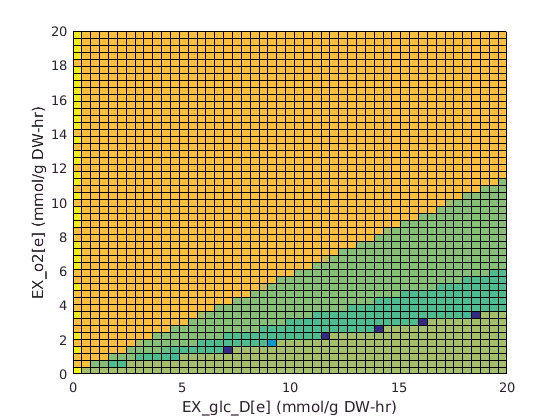

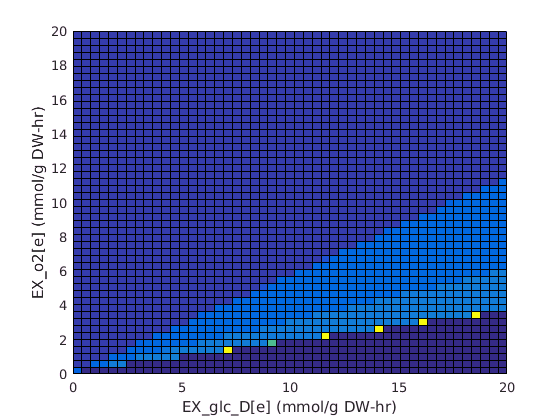

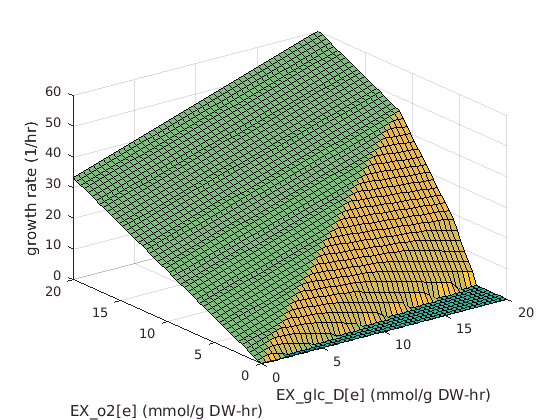

modelphpp = changeObjective (modelphpp, 'DM_atp_c_');
[growthRates, shadowPrices1, shadowPrices2] = phenotypePhasePlane(modelphpp,...
    'EX_glc_D[e]', 'EX_o2[e]');

## REFERENCES 

[1] Noronha A., et al. (2017). ReconMap: an interactive visualization of human metabolism. *Bioinformatics*., 33 (4): 605-607.

[2] Edwards, J.S. and and Palsson, B. Ø. (2000). Robustness analysis of the Escherichia coli metabolic network. *Biotechnology Progress, *16(6):927-39.

[3] Edwards, J.S., Ramakrishna, R. and and Palsson, B. Ø. (2002). Characterizing the metabolic phenotype: A phenotype phase plane analysis. *Biothechnology and Bioengineering*, 77:27-36.